# Hubble Law Part 1: Extragalactic Redshift

## Objective:

During the 1920's, there was a debate between astronomers on the existence of galaxies, or what they referred to as 'Island universes'. Known as the Great Debate, Harlow Shapley and Heber Curtis were at odds on the origins of spiral galaxies. Shapley assumed these large nebulae-like objects were held within our galaxy, which was believed to be the entirety of our universe at the time, whereas Curtis postulated that their distances spanned much further than our milky way. It wasn't until Edwin P. Hubble revealed that distant galaxies were all moving away from the Milky Way (and the Local Group) that astronomers started to believe that these were extragalactic objects. Not only that, the farther away he observed, the faster the objects were receding. Which went against the nototion that we do not hold a special place within the universe. It would take a few years for astronomers to realize that it was the expasion of the universe itself forcing these galaxies to accelerate away from all points in the universe, equally. What Hubble measured was relationship that is now known as Hubble's Law: the recessional velocity of a galaxy is proportional to its distance from us at given epoch of the universe,


$$v = H_{0} \cdot d$$


Where $v $ is the velocity along the observers line of sight in km/s, $d $ is the distance to the object in parsecs, and $H_{0}$ is the notorious Hubble constant. In our more modern context of astronomy, the Hubble constant is a fundamental constant indicating the expansion rate of spacetime and the age of our universe as a whole, and is extensively studied in the field of Cosmology. The value of the Hubble constant has seen drastic revisions throughout the last century. Even today there isn't a consensus. This is largely due to how involved the Hubble constant is within the various fields of astronomy & cosmology. It shows up in the Cosmic Microwave Background (CMB), Structure Formation of the universe, as well as our standard distance indicators (Cephiads, SNIa, etc). This is highlighted in figure below.

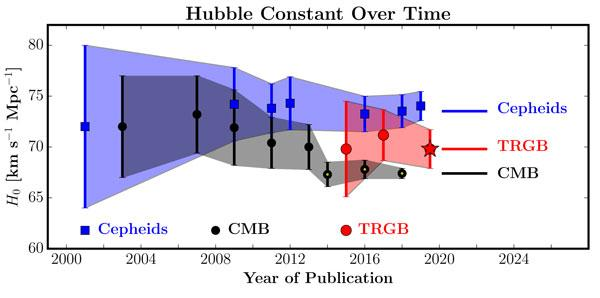

Today's measurements of the Hubble constant are far more sophisticated than that of Hubble's original calculation. His original calculations put the Hubble constant to around 500 km/s/Mpc, more than five times its current values. The reason for this discrepancy is our poor understanding of galactic distances in the early 20th century. At the time, galaxies were assumed to be much closer to us than where we measure them to be today. This lab will focus on using similar methods to determining both the velocity and distances of galaxies in an attempt to calculate the Hubble constant. Let's see if we can do better than Hubble.

## Finding Radial Velocities of Galaxies:

The velocity is relatively easy for us to measure using the Doppler effect. An object in motion (in this case, being carried along by the expansion of space itself) will have its radiation (light) shifted in wavelength. For velocities much smaller than the speed of light, we can use the regular Doppler formula: 


$$\frac{\lambda - \lambda_0}{\lambda_0} = \frac{v}{c}$$


Where $\lambda$ is the measured wavelength, $\lambda_0$ is the wavelength measured in the rest frame, $v$ is the velocity along that line of sight (radial velocity), and $c$ is the speed of light. The quantity on the left side of this equation is usually called the redshift, and is denoted by the letter $z$. The velocity of the galaxy is determined by measuring the redshift of key spectral lines within the spectrum of the galaxy. Most galaxies are rich in spectral features: for example, the "K and H" lines of ionized calcium and the H-alpha line of hydrogen. 

Let's start by reading in the spectral data of a single galaxy and try to automate the process once we have a grasp on the process on a single object. Load a single raw data file of Normalized flux (column 1) and wavelength in Angstroms (column 2).

% read the data from directory, make sure your path is correct

% create the arrays for your data

The data should now be visible in the **workspace** environment as 1-dimensional data arrays. Next, inspect the spectral data by plotting each point. Making sure not to plot it with a lines between the points, as this can cause issues in interpretting noisy spectral data.

% plot all of the data. Make it pretty

These plots of "jiggly lines" are telling us all about these galaxies, just as stellar spectra tell us all about stars. Remember the primary objects found in spiral galaxies: stars of all ages, masses, and composition; dust; and HII regions. We expect, because the bright HII regions and massive OB stars will dominate the light of a spiral galaxy, to see strong emission lines of hydrogen. We can even see that the hydrogen alpha line is the strongest peak in the spectrum at 6562.8 Angstroms. To make things visually easier to work with, let's focus the plot around some range around the suspected hydrogen alpha peak.

% plot the data with a better range

hold on % include the hold on statement so the figures carry through

## Smoothing the Spectra:

Not all of the lines come from the light of the galaxy. Each spectrum contains noise; we just cannot get away from it. You should notice that some of the spectra are much "noisier" than other spectra. This noise tends to hamper accurate identification of some of the lines. We can smooth out the function using a smoothing function. In this case, a n-point moving average smoother is build into MATLAB *smooth( ),*


$$y'(n) = (y(n-2) + y(n-1) + y(n) + y(n+1) + y(n+2))/5$$


% smooth the function

Now plot the smoothed data on top of the original data to see if we can identify the lines better. Knowing visually where the unshifted hyrdrogen alpha line will make the inspection process easier for us. To do this, we'll add an annotated vertical line to overlay on our plot using *xline(value).*

% plot the smoothed function ontop

%x1 = xline(6562.8,'--','Hygroden Alpha');
%x1.LineWidth = 1.5;
%xl.FontSize = 25;
%x1.LabelVerticalAlignment = 'Top';

## Finding the Peaks:

When looking at the smoothed data we can easily point out the various emission and absorption lines of the galaxy. For the purpose of this lab, we're concerned with only the hydrogen alpha line, which is an emission line. We can focus our attention on trying to find all of the maximums of the data instead of the minimum. It may look like a daunting task but fortunately MATLAB provides us with in-house peak finding algorithms, in the form of *findpeaks(data).* It takes in our (smoothed) data and gives pack multiple arguments, in order:

- pks $\rightarrow$ a 1D array of the peak values (maximums) 

- locs $\rightarrow$ the locations of all of the peaks, in order of pks

- w $\rightarrow$ a form of the width of the peak similar, but not exactly, to the FWHM

- p $\rightarrow$ the height of the peak relative to its baseline (where it reaches its first minimum)

% find the peaks wavelengths and flux

Now plot the peak points overlaying both our original data and the smoothed data.

% plot the peaks over the original data

From inspection we can notice that the data's hydrogen alpha peak $\lambda$ (the largest emission line peak) is to the right of the at rest hydrogen alpha line $\lambda_{o}$. Meaning, that our spectrum is redshifted and therefore moving away from us along our line of sight. The next step would be to create a method of accessing the position of the max peak, and generalize it for all our galactic spectra. (Hint: Look up the *max(data)* and the *find(condition)* functions). At the end you should have, the wavelength of the max peak $\lambda_{max}$, the value of it's prominence $f(\lambda_{max})$, and the corresponding width $w(\lambda_{max})$.

% your method of find the max peak, location, wavelength and width

## Guassian Peak Fitting Consistency Check:

The target emission peak has been located and information has been extracted $\lambda_{max}$,$f(\lambda_{max})$, $w(\lambda_{max})$. We'll use this information to check the consistency of the emission peak profile. Ideally, these emission and absorption lines are modelled by a Gaussian profile. Although this is not exactly correct. Spectral lines will be broadened and skewed by various astrophysical processes, such as rotation and pressure effects. Since we're dealing with galactic spectra, these effects are minimal compared to dense (and sometimes fastly rotating) stars. With this assumption, we'll fit a Gaussian profile over our shifted hydrogen alpha peak using the model,


$$P(x| a_{1}, a_{2}, a_{3}, a_{4}) = a_{1} \cdot \text{exp}(-((x - a_{2})/a_{3})^2) + a_{4}$$


Here $a_1$ is the peak height, $a_2$ the corresponding central wavelength, $a_3$ encodes the width, and $a_4$ is a background shift. If you need a reminder of how to implement a model to data using the Least Squares/$\chi^2$ fitting function, go back to *example1.mlx *of the tutorial. First thing, create the fittype using our above model (or any model of your choice [https://www.mathworks.com/help/curvefit/list-of-library-models-for-curve-and-surface-fitting.html#btbcvnl.).](https://www.mathworks.com/help/curvefit/list-of-library-models-for-curve-and-surface-fitting.html#btbcvnl.).)

% fit type definition 

Unlike in *example1.mlx, *where there was clearly only one peak, our data has hundreds of potential peaks that the fitting algorithm might converge to. To ensure that the fitter found our hydrogen alpha line we'll help it by setting "starting points" (or "most likely around here" points) and defining upper/lower bounds on each parameter. The starting points used will be equal to the values our max peak function found  $(a_1,a_2,a_3) =$$(f(\lambda_{max})$, $\lambda_{max}$,$w(\lambda_{max}))$. But we're missing the last parameter, the background $a_{4}$. 

You'll notice that the emission lines lay on top a background function, the full dataset slowly increasing and plateauing after $\lambda = 4500$Angstroms. If we had no emission or absorption lines in our spectra, the only thing left would be this background usually referred to as the continuum background of the spectra. $a_{4}$ is only a constant, and therefore can't encapsulate the complex function of the continuum background. Find a way to estimate the background by reducing the data to a single value. This, of course, could be the average value of our data. For better accuracy we'll probably want to focus our averaging for only the flat part of the continuum, near our emission peak in question. We'll call this variable *bkg.*

% find the background value 

Now that we have our starting points, input them into the *fit()* function using the fit type already created. As mentioned above, a starting point and both, an upper and lower bound will be given to the fitter so to converge onto the proper emission line:

- Starting Point: [$f(\lambda_{max})$, $\lambda_{max}$,$w(\lambda_{max}), bkg$]

- Upper Bound: [$a_{1}^{up},a_{2}^{up},a_{3}^{up},a_{4}^{up}$]

- Lower Bound: [$a_{1}^{low},a_{2}^{low},a_{3}^{low},a_{4}^{low}$]

Set your upper and lower bound values to what makes physically sense. Some tuning might be necessary to get the convergence right. 

% fit algorithm, refer to the tutorial 

Inspecting the fitter output is one way of checking for consistency of our values. For full visual inspection we'll plot a Gaussian function with the parameters estimated with the fitter. To do so, create a vector of x-values (using *linespace()*) and create a new Gaussian function with the x-vector as input. Finally, plot it over our figure. 

% plot it ontop of the data


hold off % stop carrying over the figure

## Putting it all Together to Calculate $\lambda_{H\alpha}$:

The goal of this lab is to find the reshifts, and correspondingly the radial velocities, of the galaxies surveyed in:(put database here). So far, we've spoken about a single galaxies spectrum. It's now time to put it all together by looping over all datasets in folder (folder name). Creating an array of all of the final radial velocities in order of the filenames. You're for loop should contain the following steps in order

- Read in the $i^{th}$ file in the directory.

- Smooth the flux data.

- Find $(f(\lambda_{max})$, $\lambda_{max}$,$w(\lambda_{max}))$ for each file.

- Calculate the redshift and save it in an array.

- Save the widths into an array.

i = 0;
redshift = zeros(length(files),1);  % an empty array for the redshifts
linewidth = zeros(length(files),1); % an empty array for the linewidths

for file = files'
    i = i + 1;   
    
    % open the ith spectra file
    
    % create arrays of the ith files data

    % find the peaks of the data
    
    % figure out the max peak values
    
    % calculate redshift and linewidth and append to arrays
    
end

The last step being to use your calculated difference $\lambda - \lambda_o$ in the Doppler shift relationship. Since we're taking a ratio of wavelengths, it doesn't matter what units we calculate our difference in. Don't forget to calculate the uncertainty for each data point. Since the width of our emission lines are larger than the resolution of the data $\Delta \lambda = 2$ angstroms, we'll use the width instead to estimate the error in our wavelengths. Propagating this to the redshift using, 

$\sigma_{v} = \frac{\partial v(\lambda)}{\partial\lambda} \sigma_{\lambda}$.

c = 299792.458; % speed of light in km/s

% calculate radial veloctiy and std, name them
% radial_vel and radial_vel_std

## Write to file:

Write the output into a file for use later.

A = [radial_vel radial_vel_std]';
fileID = fopen('set/directory/path/with/file.txt','w');
fprintf(fileID,'%5d %5d\n',A);
fclose(fileID);

## Questions:

#### (1) How would your error on the radial velocities change if we included an error for the known hydrogren alpha emission if $\sigma_{\lambda_o} = 0.01 $Angstrums?

#### (2) How might our fitting process change if we include (or exclude) parameters in our model?